% syms s t;
s = tf('s');
student_num = [3 8 1 1 3 5 4 4];

R1 = (student_num(1)+10)*5;
L1 = (student_num(2)+10)*10^-3;
C1 = (student_num(3)+10)*10^-6;
R2 = (student_num(4)+10)*5;
L2 = (student_num(5)+10)*10^-3;
C2 = (student_num(6)+10)*10^-6;

z1 = ( R1 * (1/(C1*s)) )         / ( 1/(C1*s) + R1 );
z2 = ( (1/(C1*s)) * (L1*s) * R1) / ( (1/(C1*s))*(L1*s) + (1/(C1*s))*R1 + (L1*s)*R1 );
z3 = ( (L2*s) * R2 )             / ( (L2*s) + R2 );
z4 = ( R2 * (1/(C2*s)) )         / ( R2 + (1/(C2*s)) );

% coeffs = collect((z4*z2)/(z3*z1));
% [num_sym, den_sym] = numden(coeffs);
% num = sym2poly(num_sym);
% den = sym2poly(den_sym);

xfer = minreal((z4*z2)/(z3*z1));
d_xfer = minreal((s*z4*z2)/(z3*z1));

[numSim, denSim] = tfdata(xfer, 'v');
[d_numSim, d_denSim] = tfdata(d_xfer, 'v');

% z = roots(num)
% p = roots(den)

% plot inpulse

figure(1);
clf;

xfer = chgTimeUnit(xfer, 'milliseconds')

xfer =
 
     1.212 s^2 + 6.823 s + 7.172
  ---------------------------------
  s^3 + 2.611 s^2 + 6.746 s + 6.122
 
Continuous-time transfer function.



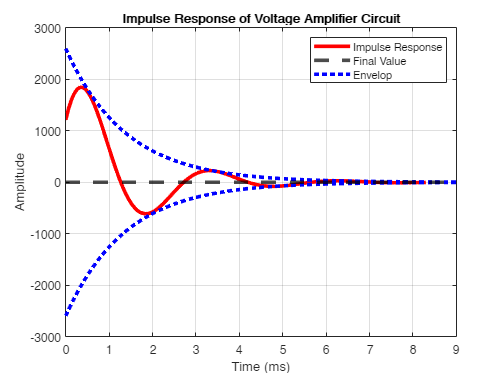

[y, t] = impulse(xfer);
plot(t, y*1000, 'LineWidth', 3, 'Color','Red')
% setoptions(h, 'TimeUnits', 'milliseconds', 'Grid', 'on');

hold on

x = linspace(0,9,1000);

K1 = 2600;
A1 = 725;
y1 = K1*exp(-A1*x/1000);
y2 = -K1*exp(-A1*x/1000);

yline(0, '--', 'LineWidth',3, 'Color', 'Black')
plot(x, y1, ':', 'LineWidth',3, 'Color', 'blue')
plot(x, y2, ':', 'LineWidth',3, 'Color', 'blue')

title('Impulse Response of Voltage Amplifier Circuit')
xlabel('Time (ms)')
ylabel('Amplitude')

legend('Impulse Response', 'Final Value', 'Envelop')

grid on
hold off

sqpuls = @(t,t1,t2) (t>= t1) & (t <= t2);
t = linspace(0, 20, 100);
% plot(t, sqpuls(t, 0, 1), '-r')

driven = lsim(xfer, sqpuls(t,0,1), t)

driven =          0
    0.3049
    0.6723
    1.0254
    1.3079
    1.4895
    1.2596
    0.8748
    0.4389
    0.0394


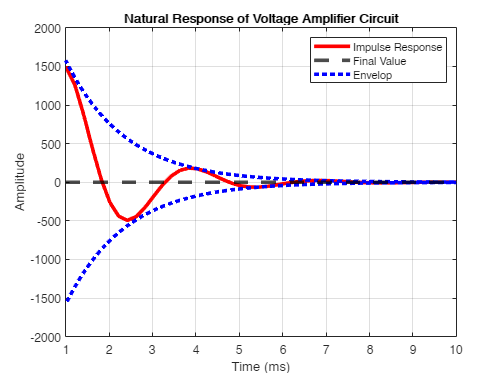

plot(t, driven*1000, 'LineWidth', 3, 'Color','Red')
axis([1,10, -2000 2000])

hold on 
x = linspace(0,20,1000);

K2 = 1580;
A2 = 725;
y3 = K2*exp(-A2*(x-1)/1000);
y4 = -K2*exp(-A2*(x-1)/1000);

yline(0, '--', 'LineWidth',3, 'Color', 'Black')
plot(x, y3, ':', 'LineWidth',3, 'Color', 'blue')
plot(x, y4, ':', 'LineWidth',3, 'Color', 'blue')

title('Natural Response of Voltage Amplifier Circuit')
xlabel('Time (ms)')
ylabel('Amplitude')

legend('Impulse Response', 'Final Value', 'Envelop')

grid on
hold off

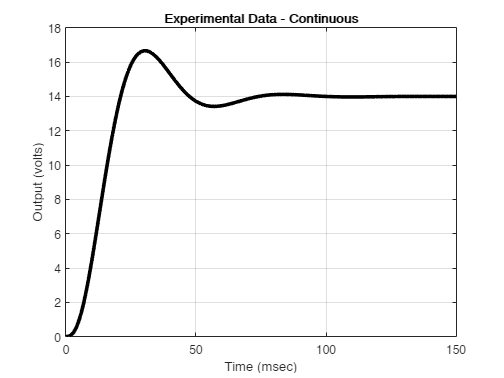

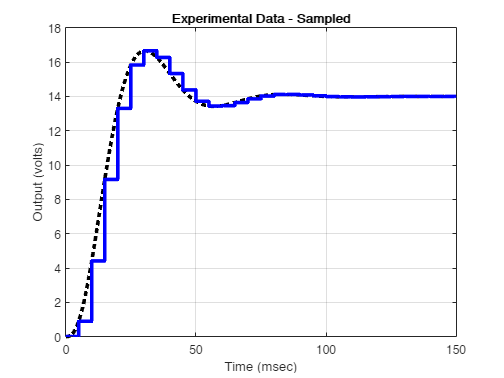

[t , y] = A1_ExpDataPlot(38113544, 3);



a = 0.45

a = 0.4500


% how to find a good a? -> slew approximation. 
% estimate how long the slew is, set 4tau = slew, tau = 1/alpha
% 
% slew = 1e-3%s
% tau = slew/2
% a = 1/tau
% this didnt work idk why

filter = a/(s+a)

filter =
 
    0.45
  --------
  s + 0.45
 
Continuous-time transfer function.



[numFilter, denFilter] = tfdata(filter, 'v');

filtered = lsim(filter, y ,t);
error = y - filtered.'

error =          0         0         0         0         0    0.7210    0.4598    0.2932    0.1869    0.1192    2.9060    1.8529    1.1815    0.7533    0.4804    4.1349    2.6366    1.6811    1.0719    4.0201    2.5633    1.6344    1.0422    0.6645    2.4599    1.5685    1.0001    0.6377    0.4066    0.9264    0.5907    0.3766    0.2402    0.1531   -0.2135   -0.1361   -0.0868   -0.0553   -0.0353   -0.7823   -0.4988   -0.3180   -0.2028   -0.1293   -0.8513   -0.5428   -0.3461   -0.2207   -0.1407   -0.6184


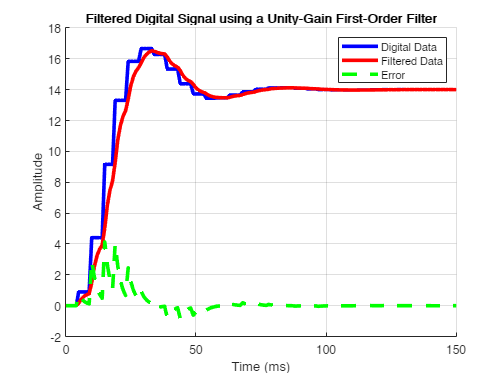


figure;
hold on

plot(t, y, 'LineWidth', 3, 'Color', 'Blue');
plot(t, filtered, 'LineWidth', 3, 'Color', 'Red');
plot(t, error,'--', 'LineWidth', 3, 'Color', 'Green')

title('Filtered Digital Signal using a Unity-Gain First-Order Filter')
xlabel('Time (ms)')
ylabel('Amplitude')

legend('Digital Data', 'Filtered Data', 'Error')

grid on
hold off